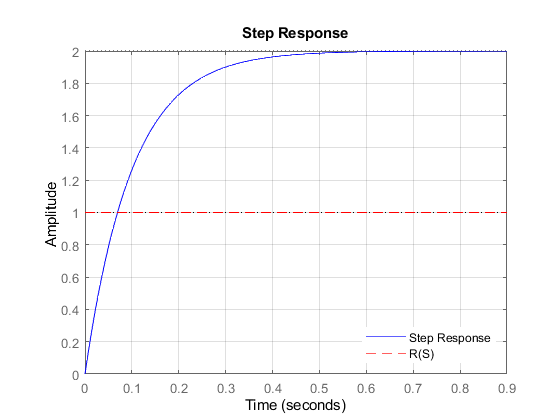

n0 = 20;
d1 = 1;
d0 = 10;
u = tf([1],[d1 0]);
x=tf([1 0],[0 1]);
ramp = tf([1],[1 0 0]);
parab = tf([1],[1 0 0 0]);
imp = tf([1]);
hs = tf([n0],[d1 d0]);
step(hs,'b',imp, 'r--')
title('Step Response');  
grid on
legend('Step Response','R(S)','Location','SouthEast')

sp=1;
[y,t]=step(hs);
sserror=abs(sp-y(end))

sserror = 0.9997

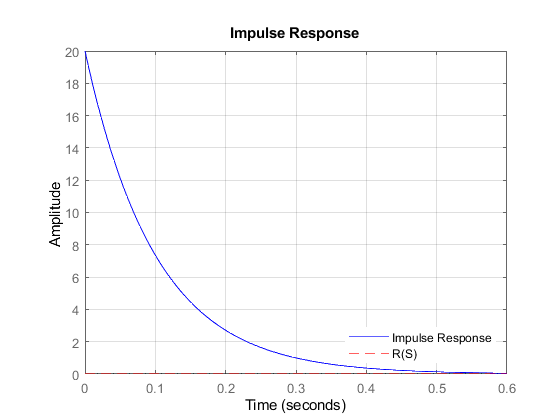

impulse(hs,'b',imp,'r--')
title('Impulse Response');
grid on
legend('Impulse Response','R(S)','Location','SouthEast')

sp2=0;
[y,t]=impulse(hs);
sserror=abs(sp2-y(end))

sserror = 0.0604

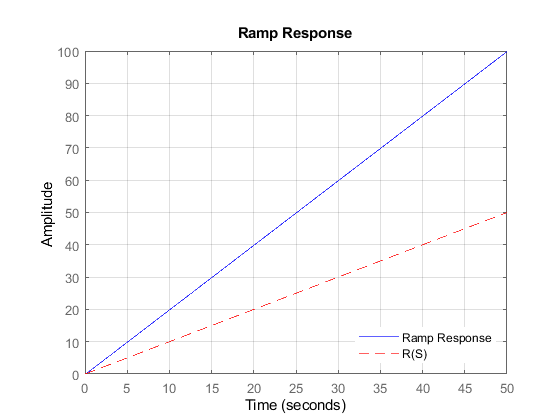

step(hs*u,'b',u,'r--')
title('Ramp Response');
grid on
legend('Ramp Response','R(S)','Location','SouthEast')

[y,t]=step(hs*u);
sp3=t(end);
sserror=abs(sp3-y(end))

sserror = 45.8517

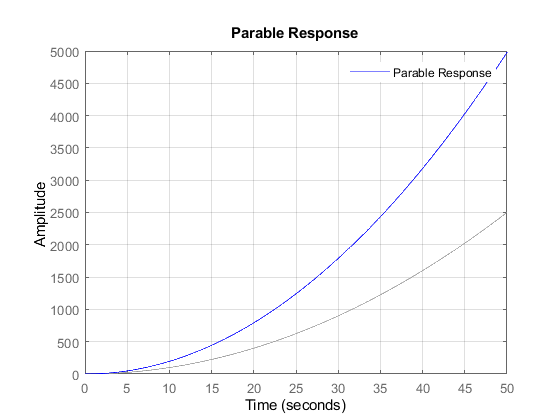

t = 0:0.05:50; 
lsim(hs,'b',t.^2,t)
title('Parable Response');
grid on
legend("Parable Response")


[y,t]=lsim(hs,t.^2,t);
sp4=t(end).^2;
sserror=abs(sp4-y(end))

sserror = 2.4800e+03